# `DEMO_01b:`    4-bar linkage analysis** - **`kinematics `alternate approach

Let's analyze the kinematics of a 4bar linkage - see Figure_01 below.  We'll refer to the system **input** as $\theta$ and the system **output** as $\phi$.  If the machine allows the system input $\theta$ to rotate a full 360 degrees then we refer to the input link $L_1$ as a CRANK.  If the system output $\phi$ can only be rotated through a limited range of angles, then we refer to the output link $L_3$ as a ROCKER.

 In this example we'll explore an alternate approach for computing the angles $\phi$ and $\alpha$.  

- Specifically we'll look at "intersecting" circles:

**Figure 01:  the 4bar linkage**

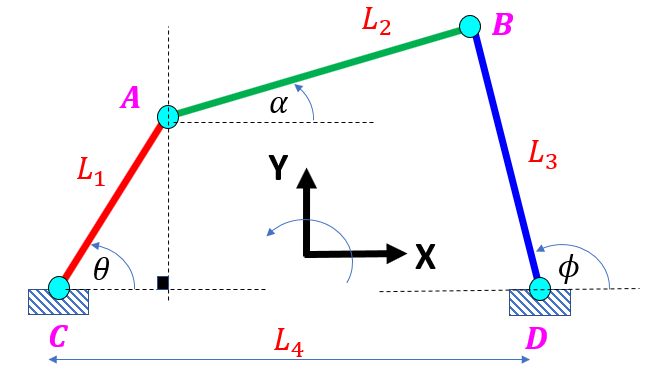      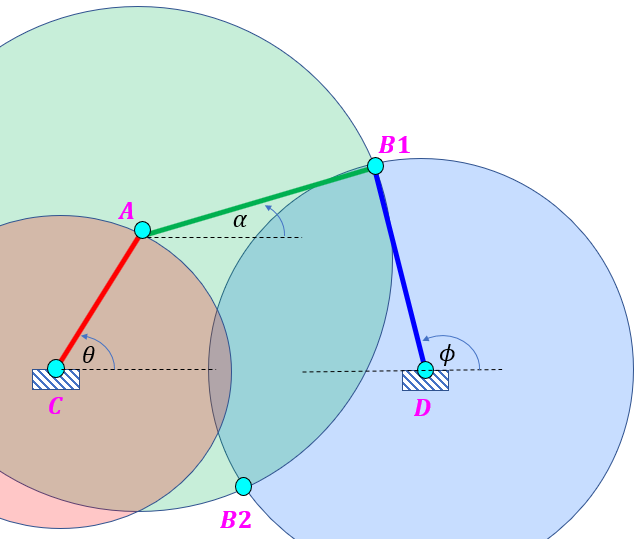

In Figure 01 above, note the following:

- the RED      circle is centered at point $C$ $\left(x_{C\;} ,y_C \right)$ and has a radius of $L_1$

- the GREEN circle is centered at point $A$$\left(x_{A\;} ,y_A \right)$  and has a radius of $L_2$

- the BLUE    circle is centered at point $D$ $\left(x_D ,y_D \right)$  and has a radius of $L_3$

We have a "valid" mechanism if the GREEN circle intersects the BLUE circle

syms L1  L2  L3  L4  real
syms  xA  yA         real
syms  x   y          real 

Specify point $C$as the origin of our co-ordinate system:

xC = sym(0);
yC = sym(0);

Point $D$ can also be defined as:

xD = L4;
yD = sym(0);

Define the Symbolic equations of our 3 circles

EQ_circ_red   = (x-xC)^2  + (y-yC)^2 == L1^2 ;
EQ_circ_green = (x-xA)^2  + (y-yA)^2 == L2^2 ;
EQ_circ_blue  = (x-xD)^2  + (y-yD)^2 == L3^2 ;

Now look for a solution where the GREEN cirlce intersects the BLUE circle, ie:  find a solution for 

- $x_B$ and $y_B$

[xB_SYM_sol, yB_SYM_sol] = solve([EQ_circ_green, EQ_circ_blue], [x,y]);

 Note:

- How the `solve` function gives a warning advising that it's solution is only valid for a specific set of conditions.  

- I have observed that for some combinations of the link lengths ... and for some specific values of theta, that the `subs()` function encounters a divide by ZERO.  If I `simplify()` the expressions, these instances don't occur.

**Simplify the solutions**

xB_SYM_sol = simplify(xB_SYM_sol)

$$xB\_SYM\_sol = \left(\begin{array}{c} \frac{{L_{2}}^{2}\,L_{4}-{L_{3}}^{2}\,L_{4}-{L_{2}}^{2}\,\mathrm{xA}+{L_{3}}^{2}\,\mathrm{xA}-L_{4}\,{\mathrm{xA}}^{2}-{L_{4}}^{2}\,\mathrm{xA}+L_{4}\,{\mathrm{yA}}^{2}+{L_{4}}^{3}+\mathrm{xA}\,{\mathrm{yA}}^{2}+\mathrm{yA}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{xA}}^{3}}{2\,\left({L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}\\ \frac{{L_{2}}^{2}\,L_{4}-{L_{3}}^{2}\,L_{4}-{L_{2}}^{2}\,\mathrm{xA}+{L_{3}}^{2}\,\mathrm{xA}-L_{4}\,{\mathrm{xA}}^{2}-{L_{4}}^{2}\,\mathrm{xA}+L_{4}\,{\mathrm{yA}}^{2}+{L_{4}}^{3}+\mathrm{xA}\,{\mathrm{yA}}^{2}-\mathrm{yA}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{xA}}^{3}}{2\,\left({L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)} \end{array}\right)$$

yB_SYM_sol = simplify(yB_SYM_sol)

$$yB\_SYM\_sol = \left(\begin{array}{c} \frac{{L_{3}}^{2}\,\mathrm{yA}-{L_{2}}^{2}\,\mathrm{yA}+{L_{4}}^{2}\,\mathrm{yA}+L_{4}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{xA}}^{2}\,\mathrm{yA}-\mathrm{xA}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{yA}}^{3}-2\,L_{4}\,\mathrm{xA}\,\mathrm{yA}}{2\,\left({L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}\\ \frac{{L_{3}}^{2}\,\mathrm{yA}-{L_{2}}^{2}\,\mathrm{yA}+{L_{4}}^{2}\,\mathrm{yA}-L_{4}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{xA}}^{2}\,\mathrm{yA}+\mathrm{xA}\,\sqrt{\left({L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}+2\,L_{4}\,\mathrm{xA}-{\mathrm{xA}}^{2}-{\mathrm{yA}}^{2}\right)\,\left(-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)}+{\mathrm{yA}}^{3}-2\,L_{4}\,\mathrm{xA}\,\mathrm{yA}}{2\,\left({L_{4}}^{2}-2\,L_{4}\,\mathrm{xA}+{\mathrm{xA}}^{2}+{\mathrm{yA}}^{2}\right)} \end{array}\right)$$

## Let's pick a machine to analyze

First specify ***numeric*** values for the lengths of the mechanism

- 
$$L_1 \;,L_2 \;,L_3 \;,L_4$$


THE_MACHINE = "MACHINE_E";

[val_L1, val_L2, val_L3, val_L4] = bh_get_preconfigured_machine(THE_MACHINE);
L_val_vec                        = [val_L1, val_L2, val_L3, val_L4]

L_val_vec =     0.5000    0.5000    0.5000    1.0000


## Do a sweep of the angle theta

theta_deg_col   = [-180:2:180]'; % DEGREES 
N               = length(theta_deg_col);
the_xB_mat      = NaN(N,2);
the_yB_mat      = NaN(N,2);

OK, let's compute $x_B$ and $y_B$ for each value of $\theta$

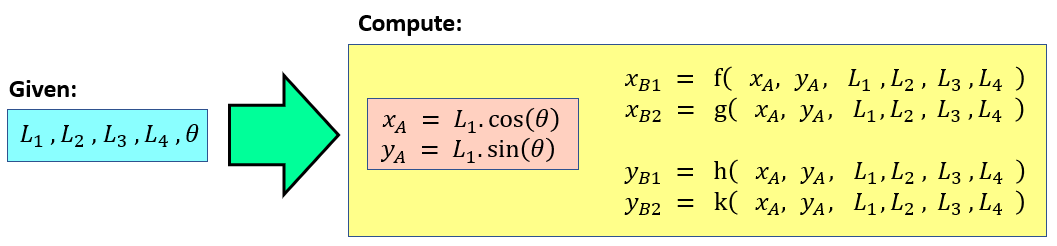

for kk=1:length(theta_deg_col)
    
   my_theta_deg =  theta_deg_col(kk);
   
   % grab the original SYMBOLIC expressions
   my_EQ_x      = xB_SYM_sol;
   my_EQ_y      = yB_SYM_sol;   
   
   % substitute in  NUMERIC values into the Symbolic expressions 
   try 
      my_symbol_list  = [xA,yA,L1,L2,L3,L4];
      my_NUMERIC_list = [L_val_vec(1)*cosd(my_theta_deg), L_val_vec(1)*sind(my_theta_deg), L_val_vec ];
      
      % use the SYMBOLIC expressions for xB and yB
      xB_val          = subs( xB_SYM_sol, my_symbol_list, my_NUMERIC_list );
      yB_val          = subs( yB_SYM_sol, my_symbol_list, my_NUMERIC_list );
      %-----------------------------------------------
      doub_the_xB     = double(xB_val);
      doub_the_yB     = double(yB_val);
   catch
      % sometimes there is a specific combination of lengths and THETA that
      % violate(?) the conditions of the solution.  And we get a "divide"
      % by ZERO error.
      doub_the_xB  = [sqrt(-1); sqrt(-1)];
      doub_the_yB  = [sqrt(-1); sqrt(-1)];
      fprintf('\n ***** SYM eval FAILURE:  [kk=%3d], theta_deg=%6.2f ', kk,theta_deg_col(kk) );
      % throw up a warning dialog too
      warndlg('*** SYM eval FAILURE ***' );
   end
   
   if(2 == length(xB_val))
      the_xB_mat(kk,:)     = doub_the_xB(:).' ; 
      the_yB_mat(kk,:)     = doub_the_yB(:).' ;       
   else
      fprintf('\n ..... NOT 2 VALS      : [kk=%3d], theta_deg=%6.2f ---> length(xB_val)=',kk,theta_deg_col(kk),length(xB_val));
      the_xB_mat(kk,1)     = doub_the_xB(1) ;   
      the_yB_mat(kk,1)     = doub_the_yB(1) ;      
   end
end

whos the_xB_mat  the_yB_mat

  Name              Size            Bytes  Class     Attributes

  the_xB_mat      181x2              5792  double    complex   
  the_yB_mat      181x2              5792  double    complex   



Depending on your specific machine (ie: $L_1 ,L_2 ,L_3 ,L_4$ ), for ***some*** of the values of $\theta$, our computations for $x_B$ and $y_B$ , will result in COMPLEX values - this indicates that the machine canNOt be configured to that pose.

So clean our  $x_B$ and $y_B$ matrices:

[xB_mat_real, yB_mat_real, tf_is_valid] = LOC_clean_xB_and_yB_matrices(the_xB_mat,  the_yB_mat);


 ---> TOTAL number of Rows processed     = 181
 ---> number of rows with COMPLEX values = 106
 ---> number of rows with     Inf values =   0


Let's tabulate our data

my_data_tab = LOC_make_a_table(theta_deg_col, xB_mat_real, yB_mat_real, tf_is_valid);

Let's compute $\phi$ and $\alpha$ for ALL entries in the table, for example:

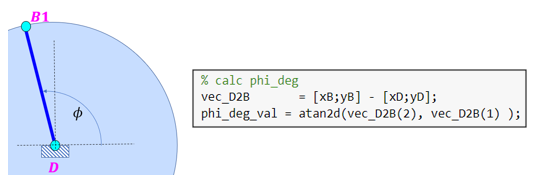

my_data_tab = LOC_calc_phi_alpha_deg_for_table(my_data_tab, L_val_vec )

my_data_tab = 181×11 table
    theta_INP_deg    is_valid    theta_deg    xB1    xB2    yB1    yB2    phi_1_deg    phi_2_deg    alpha_1_deg    alpha_2_deg
    _____________    ________    _________    ___    ___    ___    ___    _________    _________    ___________    ___________

        -180            0           NaN       NaN    NaN    NaN    NaN       NaN          NaN           NaN            NaN    
        -178            0           NaN       NaN    NaN    NaN    NaN       NaN          NaN           NaN            NaN    
        -176            0           NaN       NaN    NaN    NaN    NaN       NaN          

Where did we have **VALID** poses:

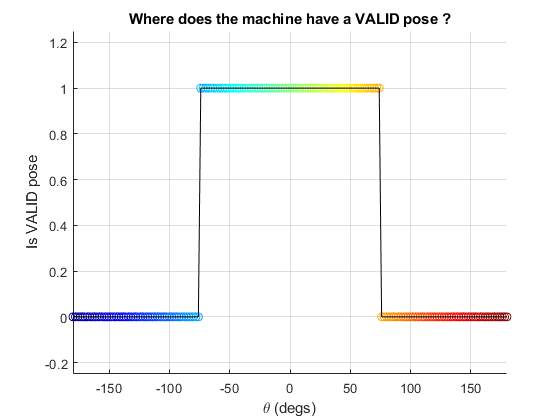

LOC_plot_valid_pose_for_theta(my_data_tab)

For the VALID poses, what do the angles for $\theta ,\phi ,\alpha$ look like ?

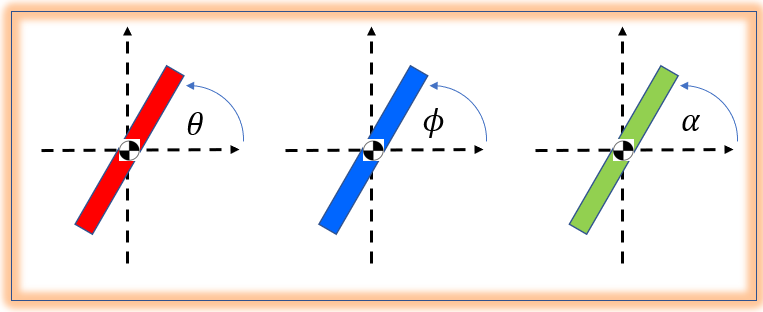

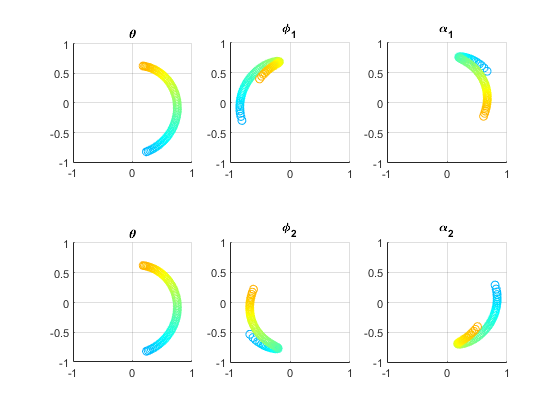

LOC_plot_round_angles(my_data_tab)

# Local functions only beyond this point

Clean the raw values for the $x_B$ and $y_B$ matrices:

function [xB_mat_real, yB_mat_real, tf_is_valid] = LOC_clean_xB_and_yB_matrices(the_xB_mat,  the_yB_mat)

    tf_xB_is_complex = abs(  imag(the_xB_mat)  ) > 1e-10;
    tf_yB_is_complex = abs(  imag(the_yB_mat)  ) > 1e-10;
    
    tf_is_complex    = tf_xB_is_complex(:,1) | tf_xB_is_complex(:,2) | ...
                       tf_yB_is_complex(:,1) | tf_yB_is_complex(:,2) ;
                
    tf_is_real       = ~tf_is_complex; 

    % So let's create some new matrices
    xB_mat_real               = NaN(size(the_xB_mat));
    yB_mat_real               = NaN(size(the_yB_mat));
    
    xB_mat_real(tf_is_real,:) = the_xB_mat(tf_is_real,:);
    yB_mat_real(tf_is_real,:) = the_yB_mat(tf_is_real,:);
    
    % And let's also test for the presence of Inf
    tf_xB_is_inf = isinf(xB_mat_real);
    tf_yB_is_inf = isinf(yB_mat_real);
    tf_is_inf    = tf_xB_is_inf(:,1) | tf_xB_is_inf(:,2) | ...
                   tf_yB_is_inf(:,1) | tf_yB_is_inf(:,2) ;

    % So clean our matrices:
    xB_mat_real(tf_is_inf,:) = NaN;
    yB_mat_real(tf_is_inf,:) = NaN;
    
    % So let's define the notion of a valid pose: 
    tf_is_valid = tf_is_real & ~tf_is_inf;   
    
    % echo a short summary of the data cleaning process
    fprintf('\n ---> TOTAL number of Rows processed     = %3d', length(tf_is_real));    
    fprintf('\n ---> number of rows with COMPLEX values = %3d', nnz(~tf_is_real));
    fprintf('\n ---> number of rows with     Inf values = %3d', nnz(tf_is_inf));    
    fprintf('\n');
end

Make a data table          

function my_table = LOC_make_a_table(theta_deg_col, xB_mat_real, yB_mat_real, tf_is_valid)

   THETA_VAL_DEG_COL        = NaN(size(theta_deg_col));
   my_tf                    = tf_is_valid;
   THETA_VAL_DEG_COL(my_tf) = theta_deg_col(my_tf);


    my_table = array2table( [theta_deg_col,  tf_is_valid, THETA_VAL_DEG_COL,  xB_mat_real,   yB_mat_real ],'VariableNames', ...
                            ["theta_INP_deg",  "is_valid",      "theta_deg",  "xB1", "xB2",  "yB1", "yB2"]);        
end

And a utility for computing $\phi$ and $\alpha$ for ALL entries in the table

function my_data_tab = LOC_calc_phi_alpha_deg_for_table(my_data_tab, L_val_vec )

   N             = size(my_data_tab,1);
   phi_deg_mat   = NaN(N,2);
   alpha_deg_mat = NaN(N,2);
   
   for kk=1:N
       theta_deg = my_data_tab.theta_deg(kk);
       
       xB1       = my_data_tab.xB1(kk);
       yB1       = my_data_tab.yB1(kk);
       xB2       = my_data_tab.xB2(kk);       
       yB2       = my_data_tab.yB2(kk);       
              
       [phi_1_deg_val, alpha_1_deg_val] = LOC_calc_phi_alpha_deg_UNIT(xB1, yB1 , theta_deg, L_val_vec);
       [phi_2_deg_val, alpha_2_deg_val] = LOC_calc_phi_alpha_deg_UNIT(xB2, yB2 , theta_deg, L_val_vec);       
       
       phi_deg_mat(kk, :)  = [  phi_1_deg_val,    phi_2_deg_val ];
       alpha_deg_mat(kk,:) = [alpha_1_deg_val,  alpha_2_deg_val ];
   end

   % add additional columns to the table
   my_data_tab.phi_1_deg   = phi_deg_mat(:,1);
   my_data_tab.phi_2_deg   = phi_deg_mat(:,2);   
   my_data_tab.alpha_1_deg = alpha_deg_mat(:,1);
   my_data_tab.alpha_2_deg = alpha_deg_mat(:,2);   
         
end

And a utility for computing $\phi$ and $\alpha$ for a given value of $x_B$ and $y_B$

function [phi_deg_val, alpha_deg_val] = LOC_calc_phi_alpha_deg_UNIT(xB, yB , theta_deg, L_val_vec)

  validateattributes(xB,       {'double'},{'scalar'});
  validateattributes(yB,       {'double'},{'scalar'});
  validateattributes(theta_deg,{'double'},{'scalar'});  
  validateattributes(L_val_vec,{'double'},{'vector', 'numel',4});  
  
  phi_deg_val   = NaN;
  alpha_deg_val = NaN;
  
  if( ~isfinite(xB) | ~isfinite(yB) | ~isreal(xB) | ~isreal(yB) | ~isfinite(theta_deg) )
     return
  end
  
  % so if we're here ... we can proceed with a calculation
  L1 = L_val_vec(1);
  L2 = L_val_vec(2);
  L3 = L_val_vec(3);
  L4 = L_val_vec(4);  
  
  xA = L1*cosd(theta_deg);
  yA = L1*sind(theta_deg);
  
  xD = L4;
  yD = 0;
  
  % calc phi_deg 
  vec_D2B       = [xB;yB] - [xD;yD];
  phi_deg_val = atan2d(vec_D2B(2), vec_D2B(1) );
  
  % calc alpha_deg  
  vec_A2B       = [xB;yB] - [xA;yA];  
  alpha_deg_val = atan2d(vec_A2B(2), vec_A2B(1) );
  
end

Plot the valid angles for $\theta$

function LOC_plot_valid_pose_for_theta(my_data_tab)
   N      = size(my_data_tab,1);
   c_rgb  = jet(N);

   x      = my_data_tab.theta_INP_deg;
   y      = double(my_data_tab.is_valid);
   
   figure;
   hax = axes;
   scatter(hax, x, y, [], c_rgb); 
   hold on
   plot(hax, x, y, '-k');
   grid on
   axis tight   
   ylim([-0.25, 1.25])
   xlabel('\theta (degs)');
   ylabel('Is VALID pose');
   title('Where does the machine have a VALID pose ?')
end

Plot the angles

function LOC_plot_round_angles(my_data_tab)
   N          = size(my_data_tab,1);
   c_rgb      = jet(N);
   figure;
   hax(1) = subplot(2,3,1);
   hax(2) = subplot(2,3,2);
   hax(3) = subplot(2,3,3);
   hax(4) = subplot(2,3,4);
   hax(5) = subplot(2,3,5);
   hax(6) = subplot(2,3,6);      
   
   LOC_plot_angle_round_UNIT(hax(1), c_rgb, my_data_tab.theta_deg);
   LOC_plot_angle_round_UNIT(hax(2), c_rgb, my_data_tab.phi_1_deg);
   LOC_plot_angle_round_UNIT(hax(3), c_rgb, my_data_tab.alpha_1_deg);
   LOC_plot_angle_round_UNIT(hax(4), c_rgb, my_data_tab.theta_deg);
   LOC_plot_angle_round_UNIT(hax(5), c_rgb, my_data_tab.phi_2_deg);
   LOC_plot_angle_round_UNIT(hax(6), c_rgb, my_data_tab.alpha_2_deg);

   title(hax(1), "\theta");
   title(hax(2), "\phi_1");
   title(hax(3), "\alpha_1");
   title(hax(4), "\theta");
   title(hax(5), "\phi_2");           
   title(hax(6), "\alpha_2");
end

plot one ROUND plot

function LOC_plot_angle_round_UNIT(hax, c_rgb, THE_DEG_ANG_VEC)

   N = length(THE_DEG_ANG_VEC);
   
   R = linspace(1,0.5, N);
   R = reshape(R, size(THE_DEG_ANG_VEC));
   
   x     = R .* cosd(THE_DEG_ANG_VEC);
   y     = R .* sind(THE_DEG_ANG_VEC);
       
   scatter(hax,x, y, [], c_rgb);           
   axis(hax,'equal');
   grid(hax,'on');
   xlim(hax,[-1,1]);
   ylim(hax,[-1,1]);

end